# **drawArrow**

Draw the arrow between two points.

## Description

Draw arrow between two points. Arrowhead is drawn at end point if form > 0, and at start point if form < 0. Arrowhead types are taken from IGES 5.3,  4.62 Leader (arrow) entity, pp 259-251 ([1]). Note that the leader always has arrowhead at the start point.

## Syntax

drawArrow( form, ad1, ad2, x1, y1, x2, y2)

drawArrow( form, ad1, ad2, x1, y1, '-delta', dx, dy)

drawArrow( form, ad1, ad2, x1, y1, '-polar', r, th)

drawArrow( form, ad1, ad2, x1, y1, x2, y2, LineSpec)

p = drawArrow(__)

## Description

drawArrow( form, ad1, ad2, x1, y1, x2, y2)  draw arrow between given points. Arrow head is at (x2,y2) if the  form > 0, and at (x1,y1) if the form < 0. 

drawArrow( form, ad1, ad2, x1, y1, '-delta', dx, dy) end point is given in delta coordinates with respect to start point. 

drawArrow( form, ad1, ad2, x1, y1, '-polar', r, th)  end point is given in polar coordinates with respect to start point.

drawArrow( form, ad1, ad2, x1, y1, x2, y2, [LineSpec](https://www.mathworks.com/help/matlab/ref/linespec.html))  set line specification.

p = drawArrow(__) returns a structure with additional data

## Method

For drawing of arrowhead **drawArrow **use function **drawArrowhead** . For usage of **drawArrowhead **see Example 1. For forms = 5,6,12 **drawArrowhead** use function **evalCircle**. For form = 10 **drawArrowhead** use function **evalBezier.**

The curve is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**form **- arrowhead type number: 1,...,12 ([1]). If form > 0 then arrow head point is the second point point i.e. the arrow is from (x1,y1) to (x2,y2), if form < 0 then the start point is the arrow tail i.e. the arrow is from (x2,y2) to (x1,y1).

   Form Meaning

-      Wedge

-      Triangle

-      Filled Triangle

-      No Arrowhead

-      Circle

-      Filled Circle

-      Rectangle

-      Filled Rectangle

-      Slash

-      Integral Sign 

-      Open Triangle

-      Dimension Origin

**ad1 **- arrowhead height (>0)

**ad2 **- arrowhead width (>0)

**x1, y1 **-  start point

**x2, y2 - **endpoint (real scalar)

or

**'-polar'|'-rtheta',r,th **- polar coordinates of end point with respect to start point

or

**'-delta',dx,dy **- relative  coordinates of end point with respect to start point

### Optional Name-Value Pair Input Arguments

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional output:

**p** - structure with fields

- p.xk, p.yk - key points: 1-start,2-end,3-mid

- p.color - line color

## Examples

### Example 1

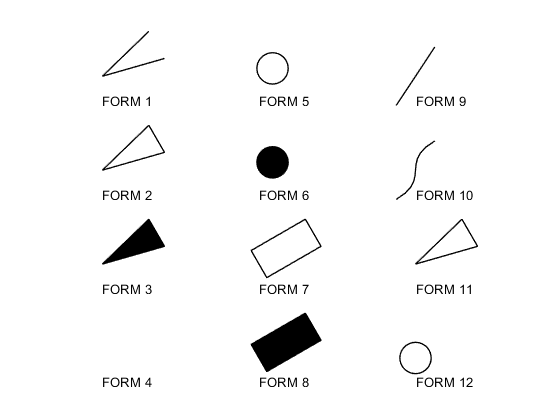

%Arrowhead types (IGES 5.3)
figure
hold on
axis equal
dx = 2.5;
dy = 1.5;
k = 0;
x = 0;
y = 3*dy;
ad2 = 0.5;
for n = 1:12
    y = y - dy;
    if n == 5 || n == 6 || n == 12
        ad1 = ad2;
    else
        ad1 = 2*ad2;
    end
    drawArrowhead(n,ad1,ad2,x,y,210)
    text(x,y-dy/4,sprintf('FORM %d',n))
    k = k + 1;
    if k > 3
        k = 0;
        x = x + dx;
        y = 3*dy;
    end
end
axis off
grid on

### Example 2

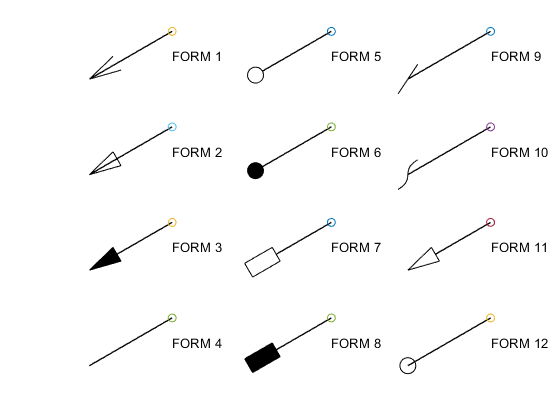

%Arrow from (x1,y1) to (x2,y2) 
figure
hold on
axis equal
dx = 2.5;
dy = 1.5;
k = 0;
x = 0;
y = 3*dy;
ad2 = 0.5/2;
for n = 1:12
    y = y - dy;
    if n == 5 || n == 6 || n == 12
        ad1 = ad2;
    else
        ad1 = 2*ad2;
    end
    % arrowhead is drawn at end point becouse form > 0
    drawArrow(n,ad1,ad2,x,y,'-polar',1.5,210)
    scatter(x,y)
    text(x,y-dy/4,sprintf('FORM %d',n))
    k = k + 1;
    if k > 3
        k = 0;
        x = x + dx;
        y = 3*dy;
    end
end
axis off

### Example 3

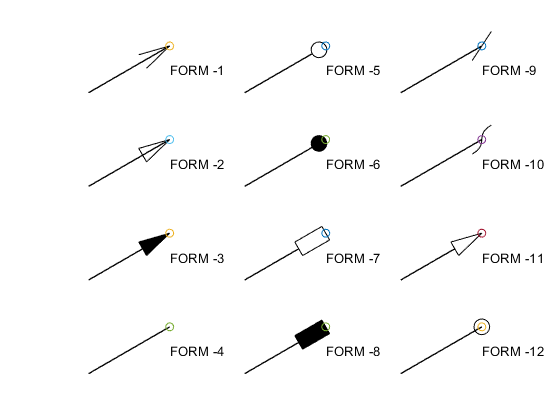

%Arrowhead from (x2,y2) to (x1,y1)
figure
hold on
axis equal
dx = 2.5;
dy = 1.5;
k = 0;
x = 0;
y = 3*dy;
ad2 = 0.5/2;
for n = 1:12
    y = y - dy;
    if n == 5 || n == 6 || n == 12
        ad1 = ad2;
    else
        ad1 = 2*ad2;
    end
    % x,y is arrow head point becouse form<0
    drawArrow(-n,ad1,ad2,x,y,'-polar',1.5,210)
    scatter(x,y)
    text(x,y-dy/4,sprintf('FORM %d',-n))
    k = k + 1;
    if k > 3
        k = 0;
        x = x + dx;
        y = 3*dy;
    end
end
axis off

### Example 4

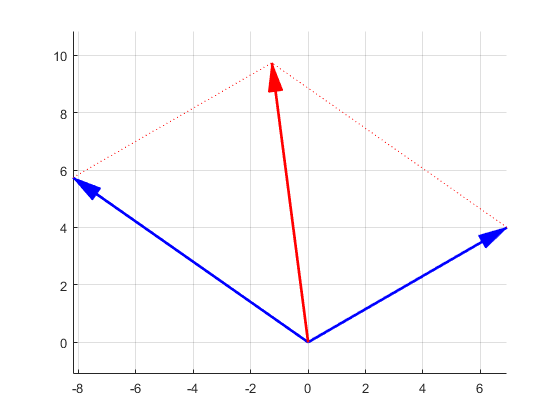

%Arrowhead types (IGES 5.3) 
figure
hold on
axis equal
dx = 2.5;
dy = 1.5;
k = 0;
x = 0;
y = 3*dy;
ad1 = 1;
ad2 = ad1/2;
an1 = 30;
an2 = 145;
F1 = 8;
F2 = 10;
a1 = drawArrow(3,ad1,ad2,0,0,'-polar',F1,an1,'LineWidth',2,'Color','b');
a2 = drawArrow(3,ad1,ad2,0,0,'-polar',F2,an2,'LineWidth',2,'Color','b');
s1 = drawLine(a2.xk(2),a2.yk(2),'-polar',F1, an1,'r:');
s2 = drawLine(a1.xk(2),a1.yk(2),'-polar',F2,an2,'r:');
drawArrow(3,ad1,ad2,0,0,s1.xk(2),s1.yk(2),'LineWidth',2,'Color','r');
grid on

## **See Also**

## References

  [1] [IGES Initial Graphics Exchange Specification IGES 5.3](http://paulbourke.net/dataformats/iges/IGES.pdf)